exercise 1

clc;
clear;
close all;

a = 1;
r = 1/4;

constant = a/(1-r);

vals = [];

for n = 0:19
    vals(n+1) = a*r^n;
end

plot(cumsum(vals), "-o", LineStyle="none");
hold on;

x = linspace(0, 20);
plot(x, ones(1, 100).*constant);

legend("approximation", "actual value", location="best");
xlabel("iteration");
ylabel("value");

exercise 2

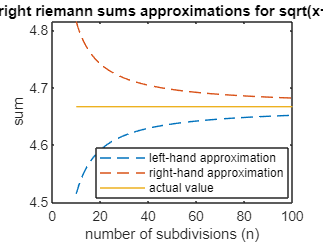

clc;
clear;
close all;

a = 0;
b = 3;

left_sums = nan(1, 91);
right_sum = nan(1, 91);

for n = 10:100
    delta_x = (b-a)/n;

    left_x = linspace(a, b-delta_x, n);
    right_x = linspace(a+delta_x, b, n);

    l = sqrt(left_x + 1) .* delta_x;
    r = sqrt(right_x + 1) .* delta_x;

    left_sums(n-9) = sum(l);
    right_sums(n-9) = sum(r);
end

x = 10:100;

plot(x, left_sums, LineStyle="--");
hold on;
plot(x, right_sums, LineStyle="--");
hold on;
plot(x, 14/3*ones(1, 91));

legend("left-hand approximation", "right-hand approximation", "actual value", location="best");
xlabel("number of subdivisions (n)");
ylabel("sum");
title("left and right riemann sums approximations for sqrt(x+1) on [0, 3]");